Calculate the front spring rate of the formula vehicle to have a front ride frequency of 3Hz – use the front sprung mass considering the mass distribution. 

f_f_Q1 = 3; %[Hz]

m_sf_Q1 = ((L-a)/L) * (m - m_usf - m_usr);

k_fspr_Q1 = m_sf_Q1 * (2*pi*f_f_Q1)^2   % [N/m]

k_fspr_Q1 = 1.3547e+05

k (front spring) = 135,470 N/m

Calculate the rear spring rate of the formula vehicle to have a front to rear ride frequency ratio of 1.2 – use the rear sprung mass considering the mass distribution. 

f_ratio_Q2 = 1.2;

f_r_Q2 = f_f_Q1 * f_ratio_Q2

f_r_Q2 = 3.6000


m_sr_Q2 = (a/L) * (m - m_usf - m_usr);

k_rspr_Q2 = m_sr_Q2 * (2*pi*f_r_Q2)^2    % [N/m]

k_rspr_Q2 = 2.0656e+05

k (rear spring) = 206,560 N/m

Calculate the front and rear spring preloads – consider the mass distribution.

g = 9.81;

F_0f_Q3 = m_sf_Q1 * g  % [N]

F_0f_Q3 = 3.7404e+03

F_0r_Q3 = m_sr_Q2 * g  % [N]

F_0r_Q3 = 3.9604e+03

F0 (front) = 3740.4 N

F0 (rear) = 3960.4 N

Calculate the front damper damping coefficient to have a damping ratio of 0.2.

damping_ratio_Q4 = 0.2

damping_ratio_Q4 = 0.2000


c_f_crit_Q4 = 2 * sqrt(k_fspr_Q1 * m_sf_Q1);

c_fdamp_Q4 = c_f_crit_Q4 * damping_ratio_Q4

c_fdamp_Q4 = 2.8748e+03

c (front damper) = 2,874.8 Ns/m

Calculate the rear damper damping coefficient to have a damping ratio of 0.2.

c_r_crit_Q5 = 2 * sqrt(k_rspr_Q2 * m_sr_Q2);

c_rdamp_Q5 = c_r_crit_Q5 * damping_ratio_Q4

c_rdamp_Q5 = 3.6527e+03

c (rear damper) = 3,652.7

Use the above calculated parameters to calculate the approximate front and rear wheel hop frequencies.

f_wheelhop_f = (1/(2*pi)) * sqrt((k_tyre + k_fspr_Q1)/m_usf)  % [Hz]

f_wheelhop_f = 21.2632


f_wheelhop_r = (1/(2*pi)) * sqrt((k_tyre + k_rspr_Q2)/m_usr)  % [Hz]

f_wheelhop_r = 20.9518

f (front wheelhop) = 21.26 Hz

f (rear wheelhop) = 20.95 Hz

Define Remaining Simulink Vehicle Model Parameters

b = L-a;

krspring = k_rspr_Q2;
kfspring = k_fspr_Q1;

F0f = F_0f_Q3;
F0r = F_0r_Q3;

cfdamper = c_fdamp_Q4;
crdamper = c_rdamp_Q5;

ktyre = k_tyre;

musf = m_usf;
musr = m_usr;

ms = m - musf - musr;

I = 1350;

z0ftyre = (m_sf_Q1 + musf) * g/ktyre;
z0rtyre = (m_sr_Q2 + musr) * g/ktyre;

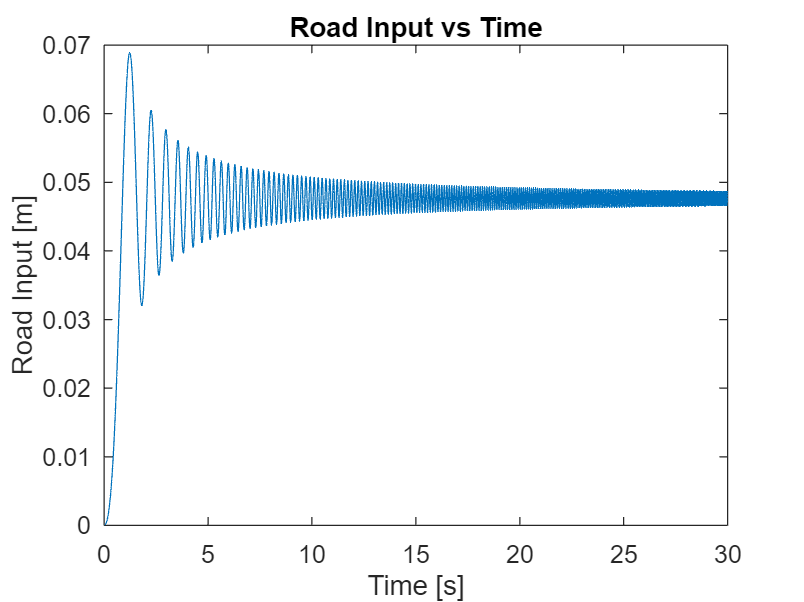

load("Vertical_Dynamics_Assignment\freqsweep_sameinput.mat");

dt = 0.005;

plot(freqsweep_sameinput.zf_road.time,freqsweep_sameinput.zf_road.data)
xlabel('Time [s]')
xlim([0 30])
ylabel('Road Input [m]')
title('Road Input vs Time')

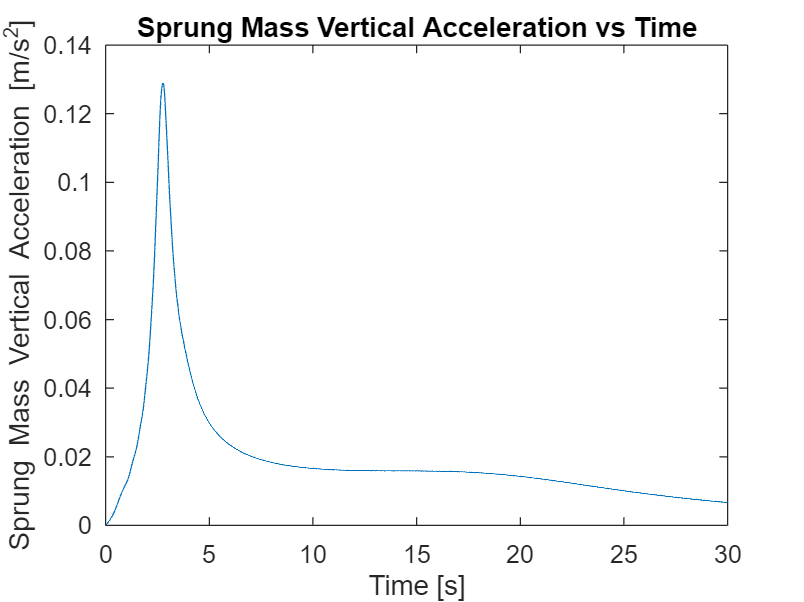


[amps,phases,freqs] = fft_VD(freqsweep_sameinput.zsdotdot.data,dt);

plot(freqs,amps)
xlabel('Time [s]')
xlim([0 30])
ylabel('Sprung Mass Vertical Acceleration [m/s^2]')
title('Sprung Mass Vertical Acceleration vs Time')

Heave Natural Frequency = 2.8 Hz (1dp)

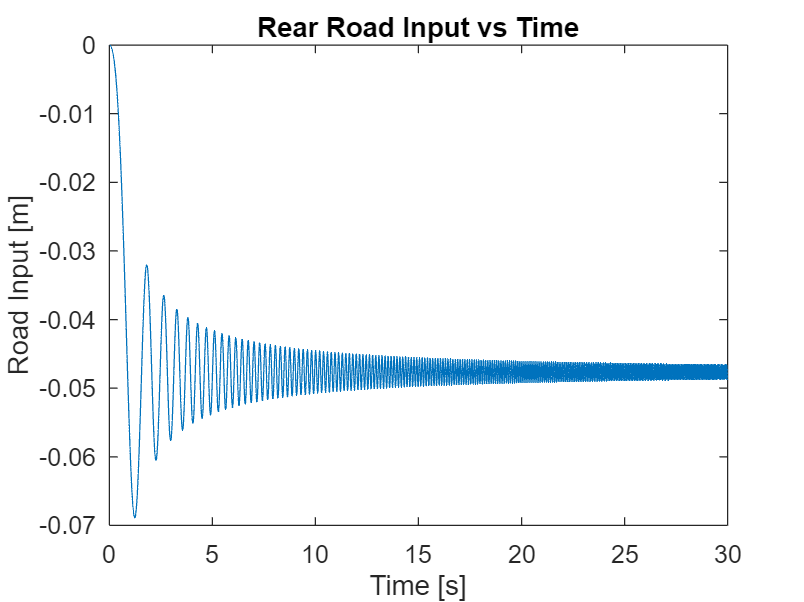

load("Vertical_Dynamics_Assignment\freqsweep_oppositeinput.mat");

plot(freqsweep_oppositeinput.zr_road.time,freqsweep_oppositeinput.zr_road.data)
xlabel('Time [s]')
xlim([0 30])
ylabel('Road Input [m]')
title('Rear Road Input vs Time')

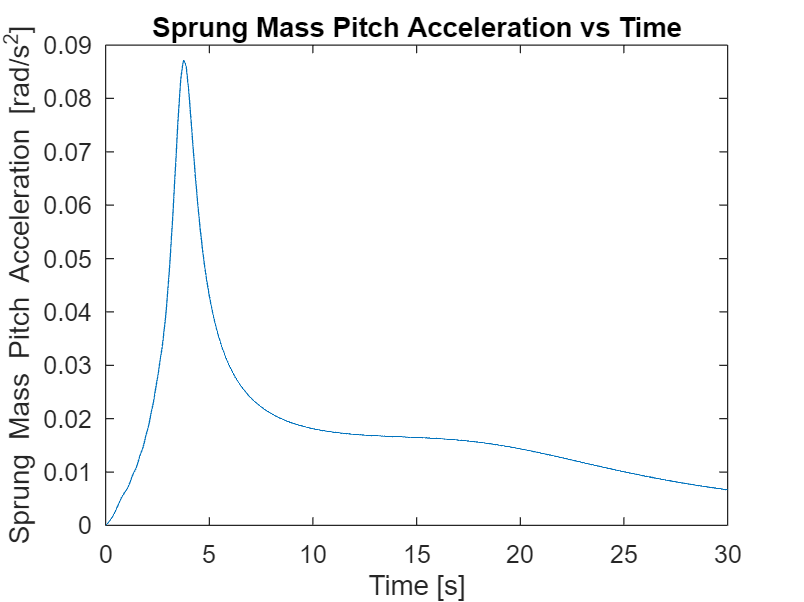


[ampspitch,phasespitch,freqspitch] = fft_VD(freqsweep_oppositeinput.pitchdotdot.data,dt);

plot(freqspitch,ampspitch)
xlabel('Time [s]')
xlim([0 30])
ylabel('Sprung Mass Pitch Acceleration [rad/s^2]')
title('Sprung Mass Pitch Acceleration vs Time')

Pitch Natural Frequency = 3.8 Hz (1dp)